# CALM CHARACTERIZATION

clear all
clc

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\dati di calibrazione\calm_camera_calibration.mat");

intrinsics = calm_camera_calibration.Instrinsics_params;
extrinsics = calm_camera_calibration.Extrinsics_params;

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\CameraCalibratorApp\cameraParams.mat");


folder = ['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_robot\ripetibilità_paus'];

% Carica il video
video_path = ['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\' ...
    'Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_user\user_test1.mpg']; % Inserisci il percorso del video

% Estrarre l'ultima stringa
[~, fileName, fileExt] = fileparts(video_path);

video = VideoReader(video_path);

frames_number = video.NumFrames

frames_number = 454

frame_rand = randi([0,frames_number])

frame_rand = 370

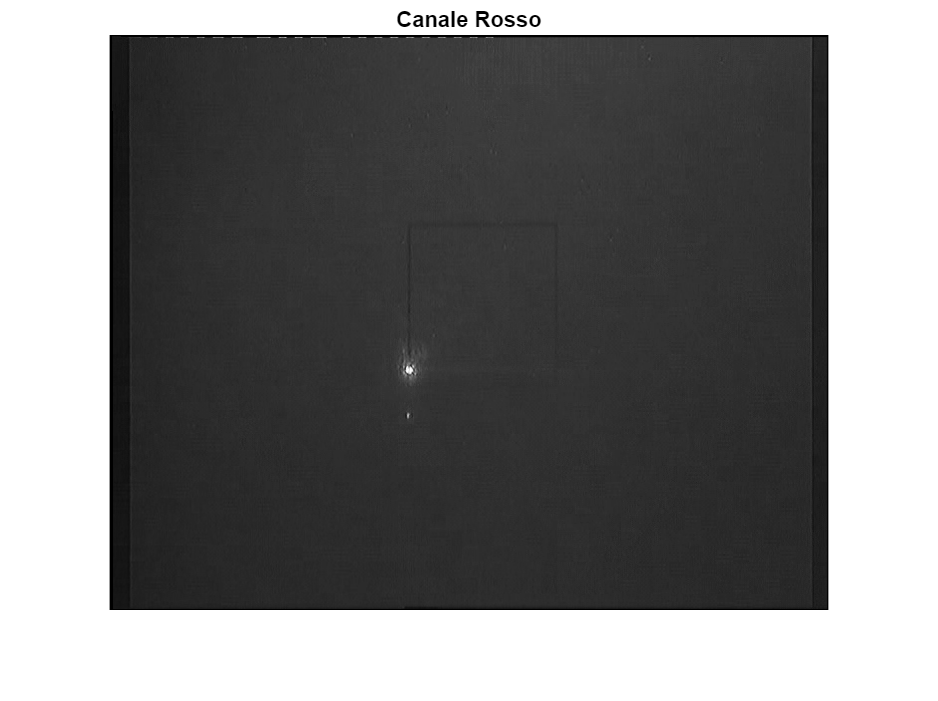

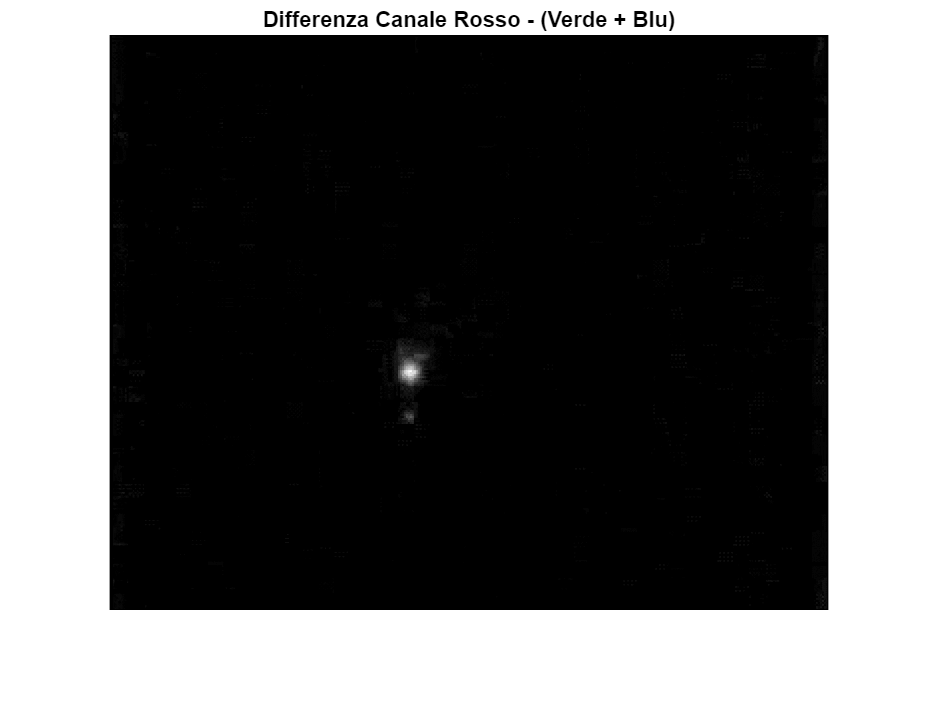

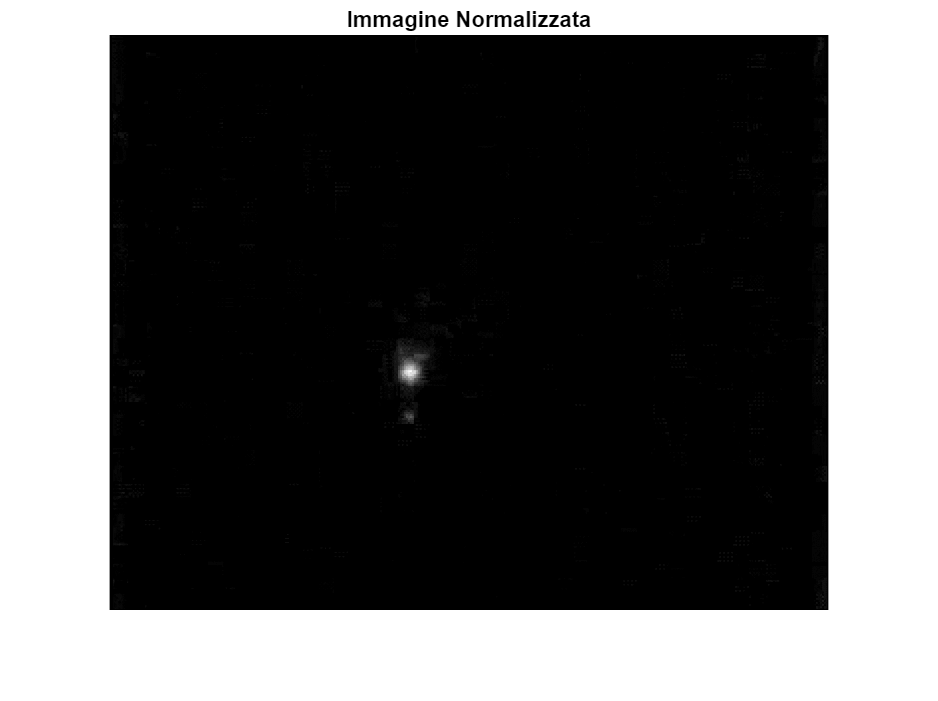

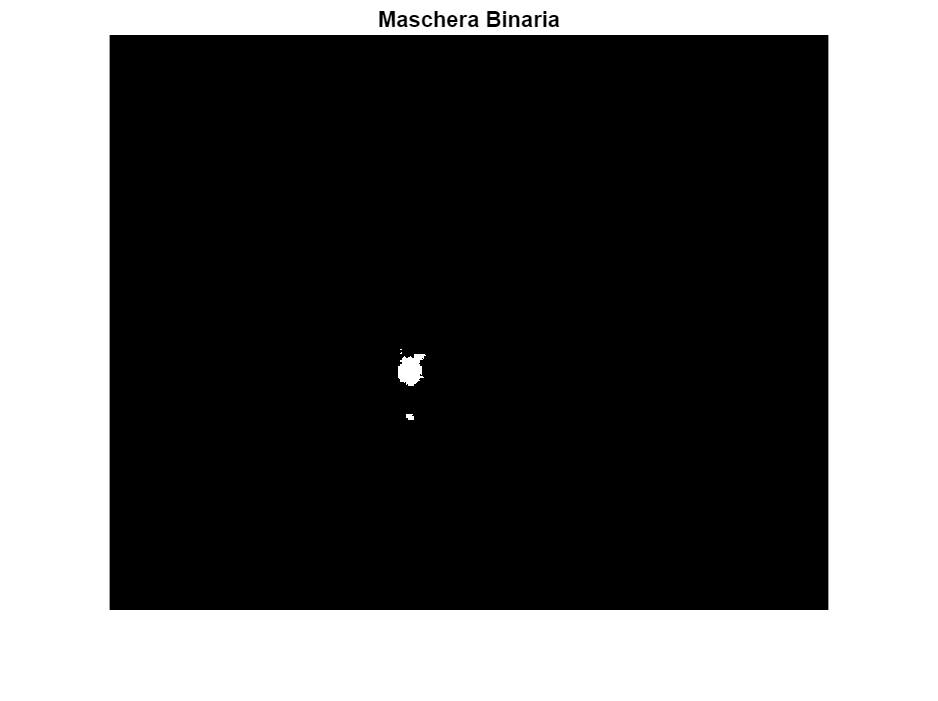

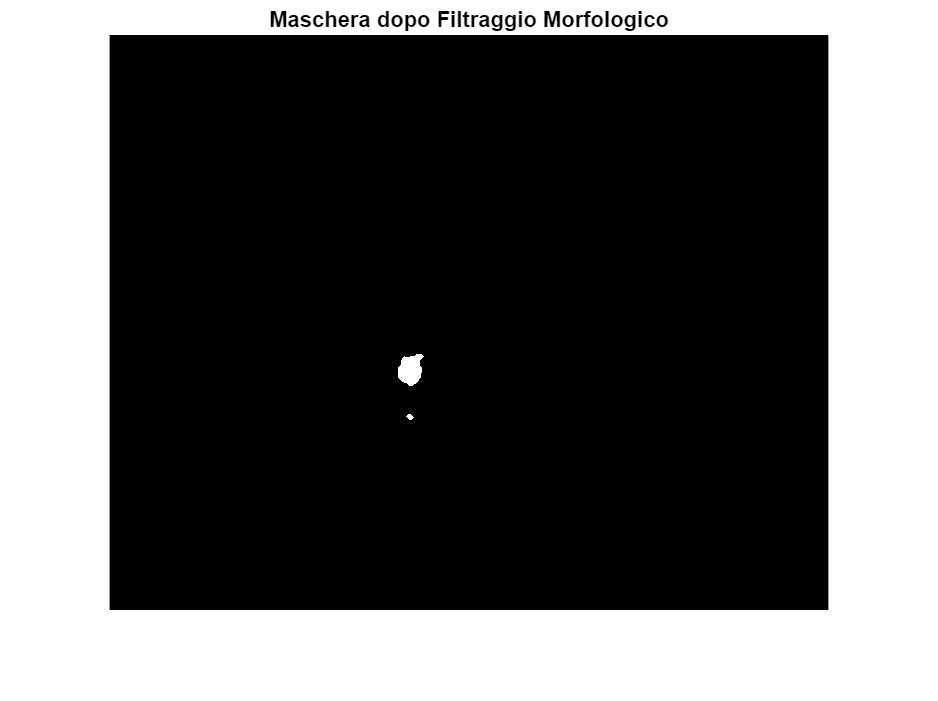

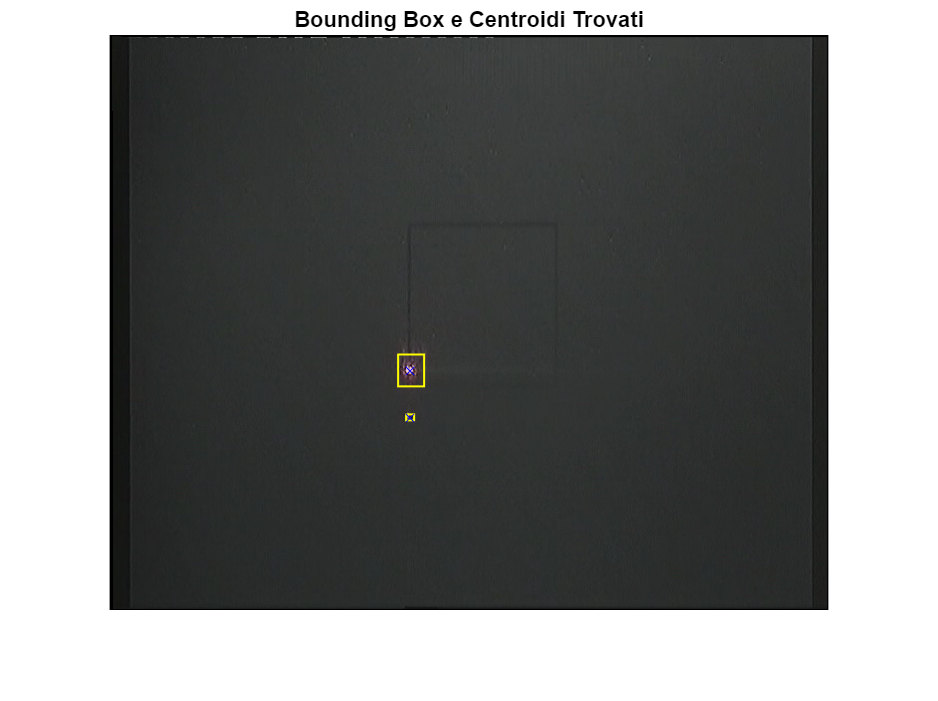

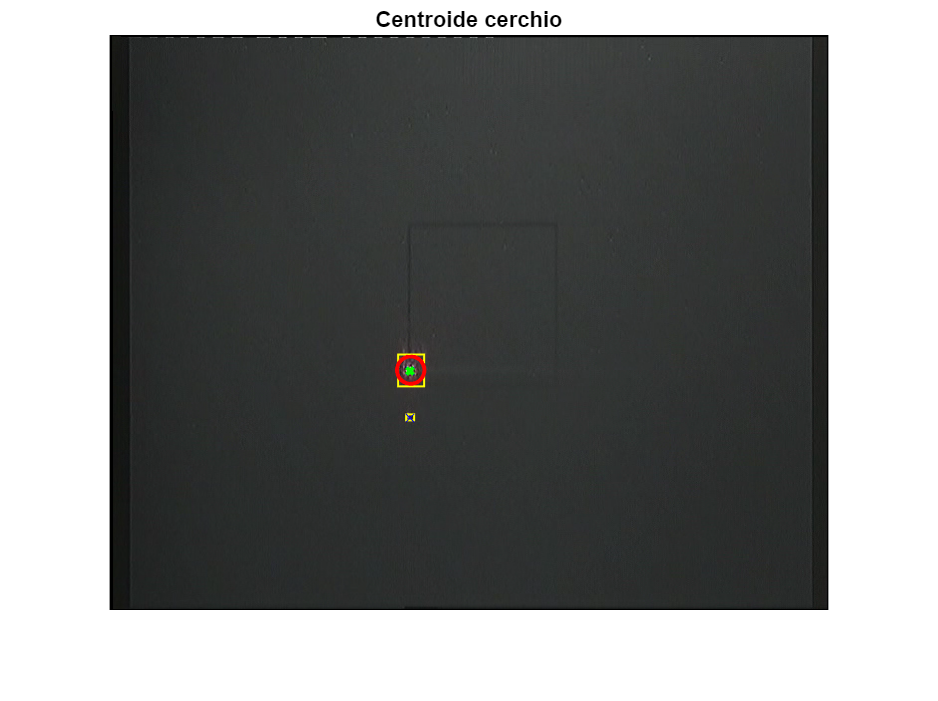

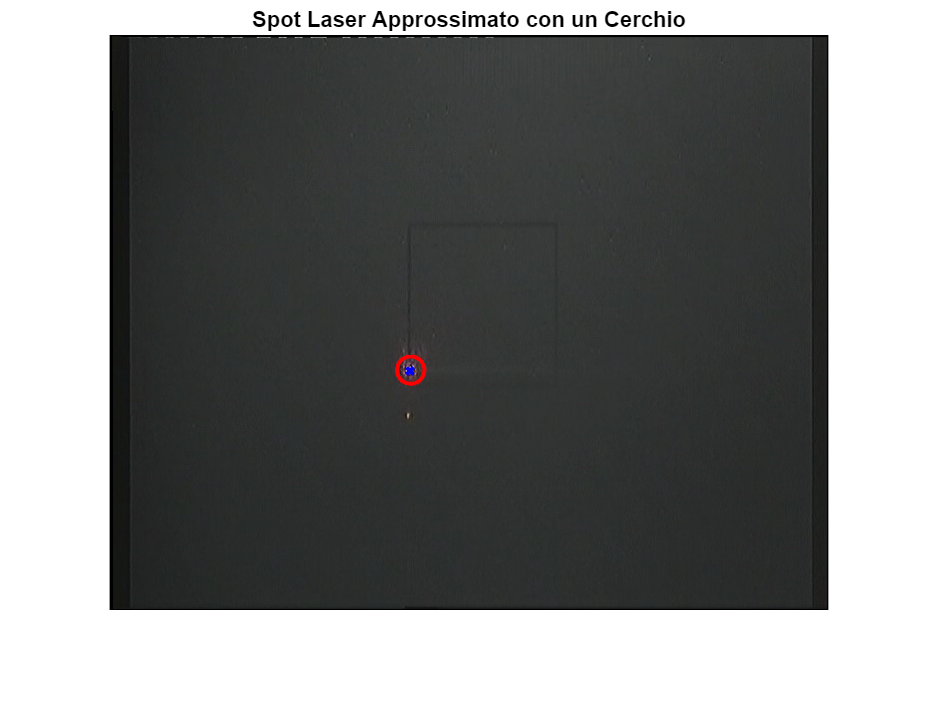

% Parametri per l'elaborazione video
vidout_on = true; % Salva il video processato
fps_out = 25;
video_name = fullfile(['C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\' ...
    'Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\improvement_test\dark_720x576\test_accuratezza_user'], ...
    [fileName, '_processed']); % video_name = [fileName, '_processed'];

if vidout_on
    writerObj = VideoWriter([video_name, '.mp4'], 'MPEG-4');
    writerObj.FrameRate = fps_out;
    open(writerObj);
end

% Preallocazione matrice per traiettoria
coords_matrix = NaN(video.NumFrames, 3); % Colonne e righe
trajectory_mask = zeros(video.Height, video.Width); % Maschera accumulativa per la traiettoria

frame_index = 0; % Indice del frame corrente

problematic_frame_indices = []; % Lista per i frame in cui lo spot non è stato rilevato

% Loop per analizzare e tracciare ogni frame
while hasFrame(video)

    frame_index = frame_index + 1;

    try
        
        % Leggi e correggi il frame
        frame = readFrame(video); % Leggi il frame corrente. frame is an H x W x B matrix where:
        %  H is the image frame height
        %  W is the image frame width
        %  B is the number of bands in the image (e.g. 3 for RGB)
        [frame_Undist, frameIntrinsics] = undistortImage(frame, cameraParams);

        % Esegui il rilevamento dello spot laser (coordinate in pixels)
        if (frame_index == frame_rand)
            coords = spot_detector(frame_Undist, 1, 1);
        else
            coords = spot_detector(frame_Undist, 0, 0);
        end


        if ~isnan(coords.row) && ~isnan(coords.col)
            row = round(coords.row);
            col = round(coords.col);

            % Aggiorna matrice e maschera
            coords_matrix(frame_index, :) = [frame_index, col, row];
            trajectory_mask(row, col) = 1;

            % Disegna il cerchio sul punto corrente
            frame_Undist = insertShape(frame_Undist, 'FilledCircle', [col, row, 5], 'Color', 'green', 'Opacity', 1);

            % Disegna le linee guida
            color = 180; % Grigio
            frame_Undist(row, :, 1) = color; % Linea orizzontale (R)
            frame_Undist(row, :, 2) = color; % Linea orizzontale (G)
            frame_Undist(row, :, 3) = color; % Linea orizzontale (B)

            frame_Undist(:, col, 1) = color; % Linea verticale (R)
            frame_Undist(:, col, 2) = color; % Linea verticale (G)
            frame_Undist(:, col, 3) = color; % Linea verticale (B)

        else
            % Spot laser non rilevato
            problematic_frame_indices = [problematic_frame_indices, frame_index];
            fprintf('Spot non rilevato nel frame %d\n', frame_index);
        end

        % Sovrapposizione della traiettoria
        [rows, cols] = find(trajectory_mask);
        for k = 1:length(rows)
            frame_Undist(rows(k), cols(k), :) = [0, 255, 0]; % Verde
        end

        % Scrivi il frame processato nel file video
        if vidout_on
            writeVideo(writerObj, frame_Undist);
        end

        catch ME
        fprintf('Errore nel frame %d: %s\n', frame_index, ME.message);
        continue; % Salta il frame problematico
    end

end

% Chiudi il file video
if vidout_on
    close(writerObj);
end

if ~isempty(problematic_frame_indices)
    fprintf('Frame problematici: %s\n', num2str(problematic_frame_indices));

    % Identifica le righe con valori NaN in colonna 2 o 3
    rows_with_nan = isnan(coords_matrix(:, 2)) | isnan(coords_matrix(:, 3));

    % Elimina queste righe dalla matrice
    coords_matrix(rows_with_nan, :) = [];

else
    fprintf('Tutti i frame processati correttamente.\n');
end

Tutti i frame processati correttamente.


## Check Trajectory

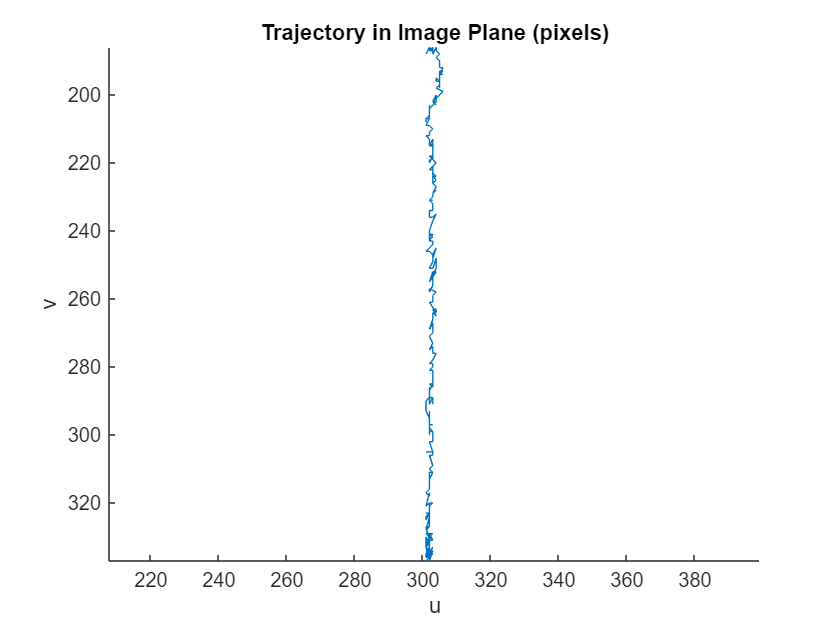

figure
plot(coords_matrix(:,2), coords_matrix(:,3))
xlabel 'u'
ylabel 'v'
title('Trajectory in Image Plane (pixels)')
box off
axis equal
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo

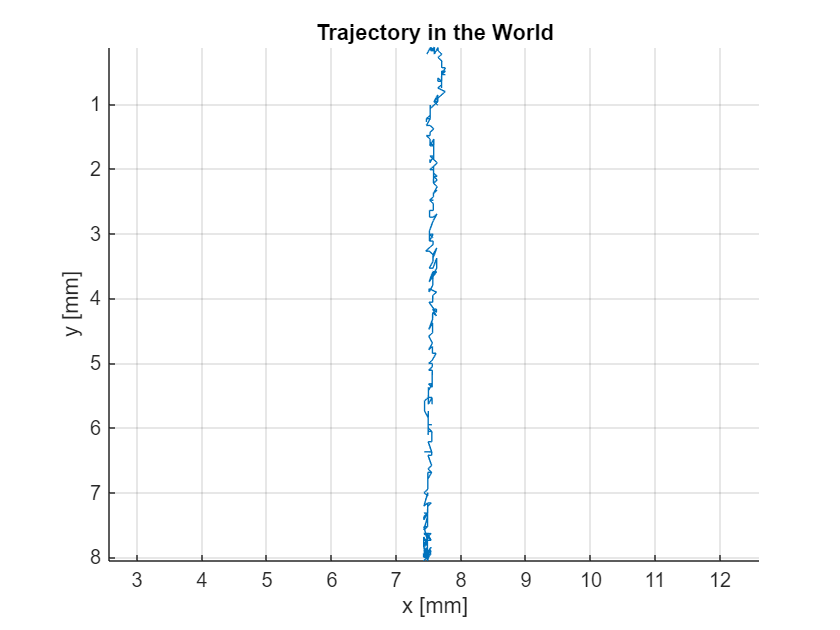

laserWorldPoints = zeros(length(coords_matrix), 2);
 
for i = 1:length(coords_matrix)

    laserWorldPoints(i,:) = img2world2d(coords_matrix(i,2:3), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
plot(laserWorldPoints(:,1), laserWorldPoints(:,2));
hold on
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;

title('Trajectory in the World')
box off

## Analisi in frequenza per la rimozione del ripple

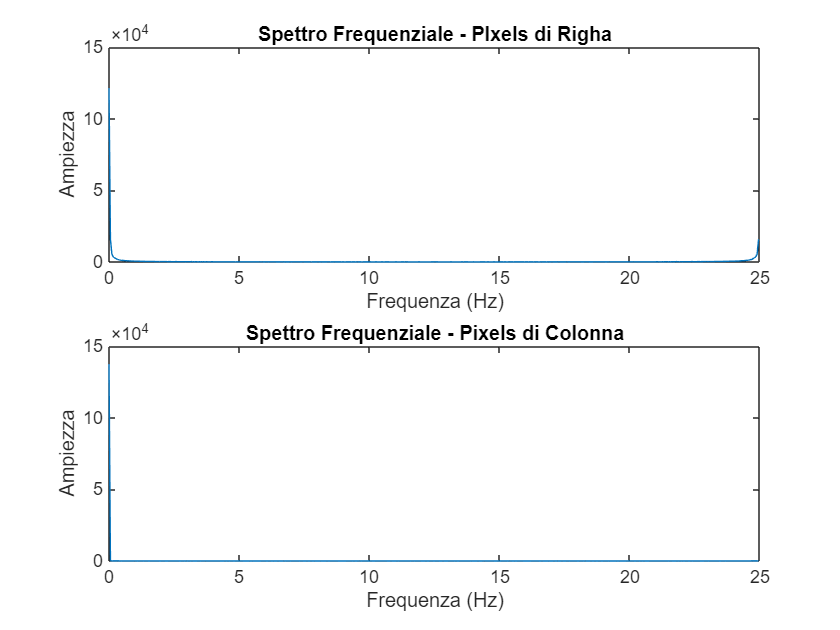

% Analisi in frequenza per rimuovere il ripple dalle coordinate del laser
% frame_rate: Frequenza di campionamento (25 Hz)
% cutoff_frequency: Frequenza di taglio del filtro passa-basso (in Hz)

% Calcola la Trasformata di Fourier delle coordinate
N = length(coords_matrix(:,2));
Fs = video.FrameRate;  % Frequenza di campionamento (25 Hz)

% Trasformata di Fourier (DFT)
F_row = fft(coords_matrix(:,3));
F_col = fft(coords_matrix(:,2));

% Frequenze associate a ciascun punto nella DFT
f = (0:N-1)*(Fs/N);  % Frequenze di Nyquist

% Spettro di ampiezza
figure;
subplot(2, 1, 1);
plot(f, abs(F_row));
title('Spettro Frequenziale - PIxels di Righa');
xlabel('Frequenza (Hz)');
ylabel('Ampiezza');

subplot(2, 1, 2);
plot(f, abs(F_col));
title('Spettro Frequenziale - Pixels di Colonna');
xlabel('Frequenza (Hz)');
ylabel('Ampiezza');

## Filtered Trajectory

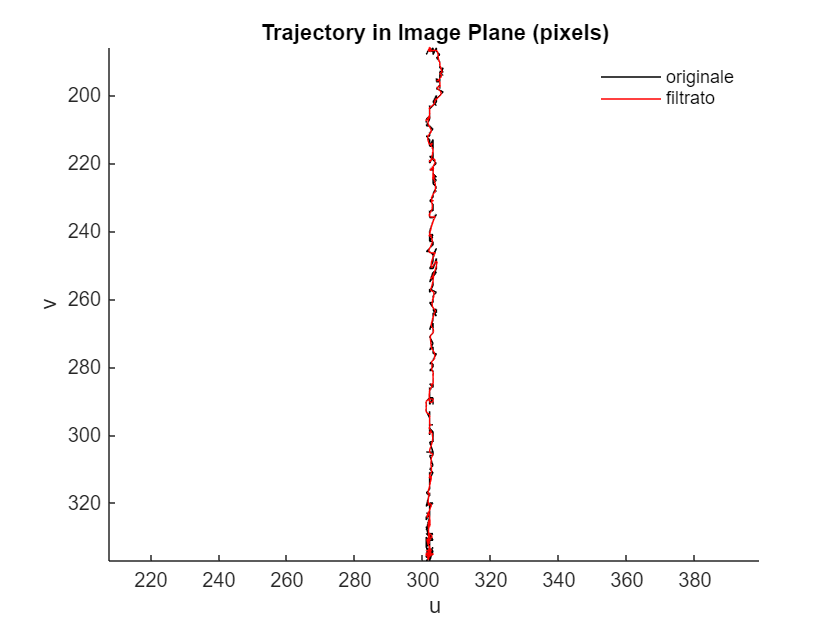

% Parametri del filtro passa-basso
cutoff_freq = 6; % Frequenza di taglio in Hz
[b, a] = butter(4, cutoff_freq / (Fs / 2), 'low'); % Filtro Butterworth: cutoff_freq / (Fs / 2) normalizza la frequenza di taglio rispetto alla frequenza di Nyquist (che è Fs/2 = 12.5Hz)

% Applica il filtro passa-basso con filtfilt
filtered_row = filtfilt(b, a, coords_matrix(:,3));
filtered_col = filtfilt(b, a, coords_matrix(:,2));

% Plotta il confronto
figure;
hold on;
plot(coords_matrix(:,2), coords_matrix(:,3), 'k', 'DisplayName', 'Originale'); % Segnale originale
plot(filtered_col, filtered_row, 'r', 'DisplayName', 'Filtrato (filtfilt)'); % Segnale filtrato
legend('originale', 'filtrato');
legend box off
xlabel 'u'
ylabel 'v'
axis equal;
title('Trajectory in Image Plane (pixels)')
box off
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo

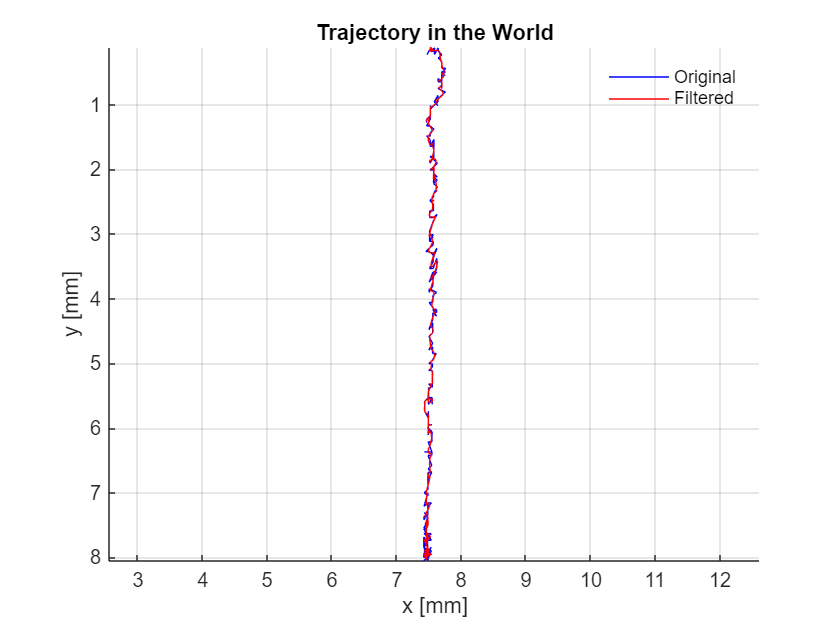

coords_matrix_filtered = [filtered_col, filtered_row];

for i = 1:length(coords_matrix_filtered)

    laserWorldPoints_filtered(i,:) = img2world2d(coords_matrix_filtered(i,1:2), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
plot(laserWorldPoints(:,1), laserWorldPoints(:,2),'b');
hold on
plot(laserWorldPoints_filtered(:,1), laserWorldPoints_filtered(:,2),'r');
legend('Original', 'Filtered')
legend box off
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
title('Trajectory in the World')
box off

% Salvo ogni variabile con il rispettivo nome nel folder 
variabili = {'coords_matrix', 'laserWorldPoints', 'laserWorldPoints_filtered'};
for i = 1:numel(variabili)
    varName = variabili{i};
    fileName = fullfile(folder, [varName, '.mat']);
    save(fileName, varName);
end

Unrecognized function or variable 'folder'.

## Confronto laser trajectory vs target trajectory

- **CIRCONFERENZA**

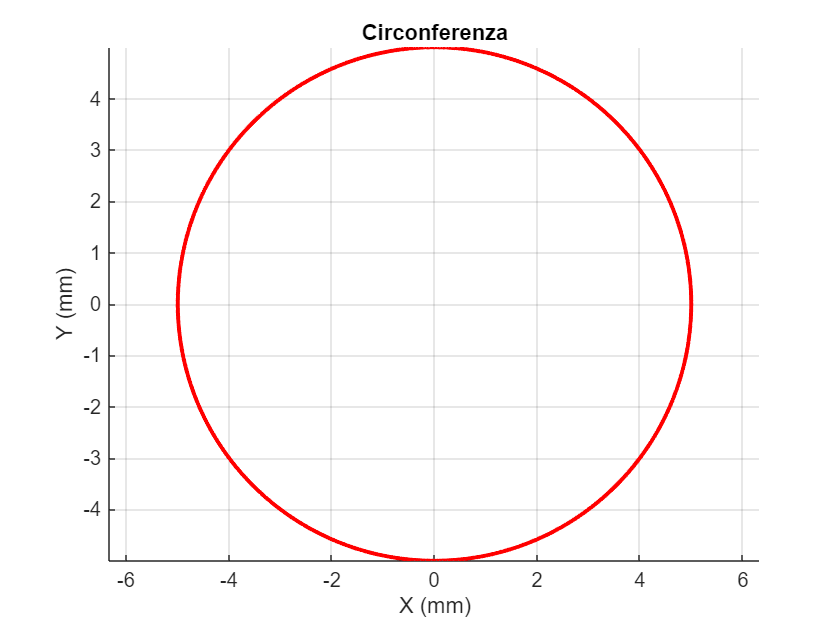

% Define The Reference Trajectory 
% r  = 5;
% x_target = r * sin(2*pi*0:0.001:2*pi);
% y_target = r * cos(2*pi*0:0.001:2*pi);
theta = linspace(0, 2*pi, length(coords_matrix(:,2))*5);% Angolo da 0° a 360°
r = 5; % Raggio in mm
x_target = r * cos(theta); x_target = x_target';
y_target = r * sin(theta); y_target = y_target';

% Visualizzazione
figure
plot(x_target, y_target, 'r-', 'LineWidth', 2);
xlabel('X (mm)');
ylabel('Y (mm)');
axis equal;
title('Circonferenza');
grid on;
box off

## Identificare l'offset tra i sistemi

L'offset rappresenta la differenza tra il punto di origine della traiettoria target e quello della traiettoria misurata nel sistema di coordinate del mondo

offset_x = max(laserWorldPoints_filtered(:,1)) - max(x_target);  % offset_x = laserWorldPoints(1,1) - x_target(1)

offset_x = 12.0294

offset_y = max(laserWorldPoints_filtered(:,2)) - max(y_target); % offste_y = laserWorldPoints(1,2) - y_target(1)

offset_y = 2.6314

## Applicare l'offset alla traiettoria target

Una volta calcolato l'offset, trasla la traiettoria target per allinearla con la traiettoria misurata:

x_target_aligned = x_target + offset_x;
y_target_aligned = y_target + offset_y;
% Ora entrambe le traiettorie si trovano nello stesso sistema di coordinate

## Confrontare le traiettorie

Dopo l'allineamento, puoi confrontare punto per punto le due traiettorie

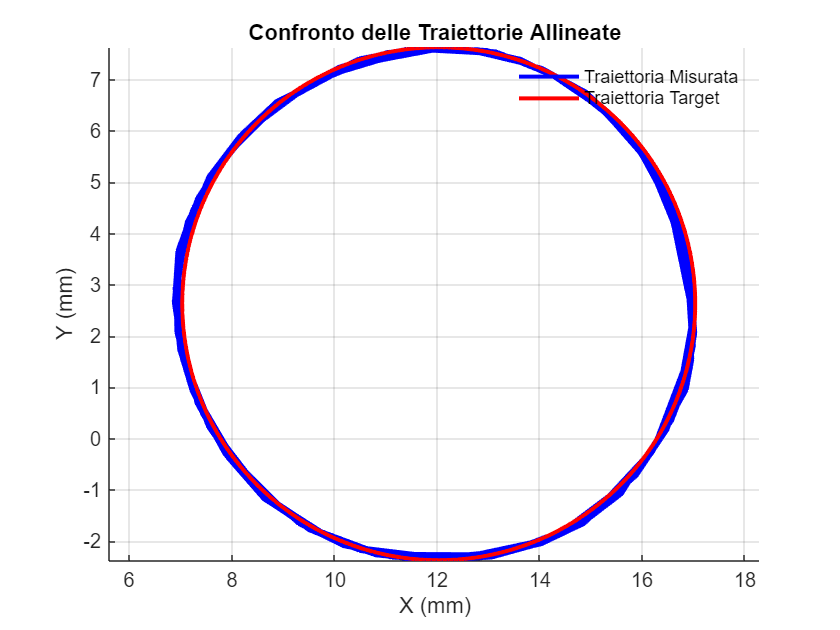

figure
plot(laserWorldPoints_filtered(:,1), laserWorldPoints_filtered(:,2), 'b-', 'LineWidth', 2); % Traiettoria misurata
hold on;
plot(x_target_aligned, y_target_aligned, 'r-', 'LineWidth', 2); % Traiettoria target allineata
legend('Traiettoria Misurata', 'Traiettoria Target');
legend box off
xlabel('X (mm)');
ylabel('Y (mm)');
axis equal;
grid on;
% set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
title('Confronto delle Traiettorie Allineate');
box off

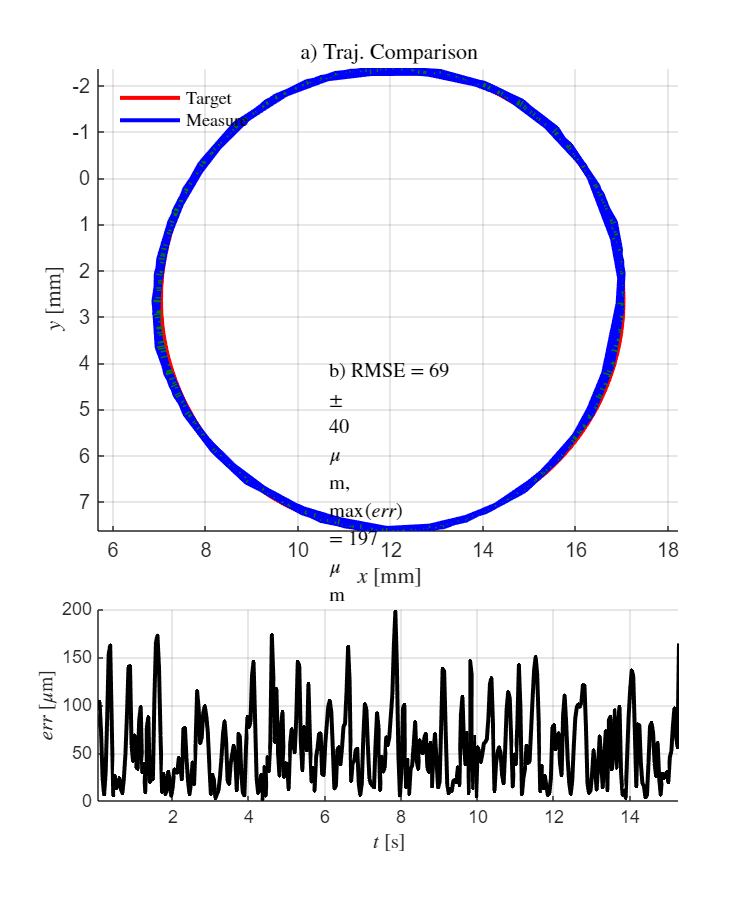

RMSE     = 69 ± 40 µm
max(err) = 197 µm


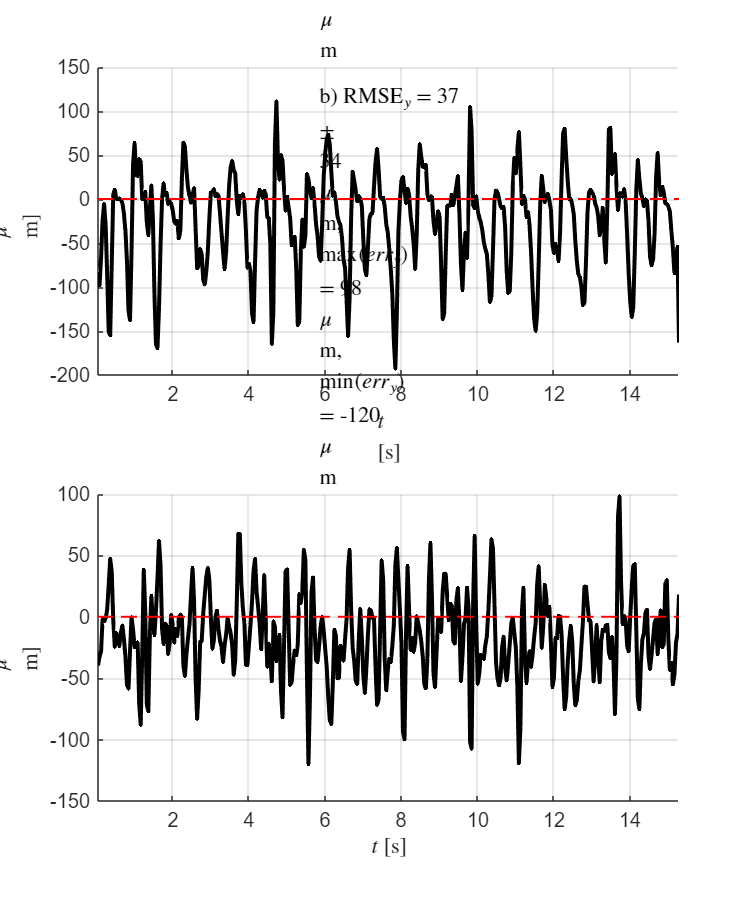

% t is time
t = (1:1:length(coords_matrix(:,2)))'/ video.FrameRate;
[rmse, rmse_x, rmse_y, std_f, std_x ,std_y, figHandles] = circ_rmse(x_target_aligned, y_target_aligned, laserWorldPoints_filtered(:,1) ,laserWorldPoints_filtered(:,2), t);

rmse_tot = rmse;
std_tot = std_f;
rmse_x = rmse_x;
std_x = std_x;
rmse_y = rmse_y;
std_y = std_y;

data = [rmse_tot, std_tot; rmse_x, std_x; rmse_y, std_y]

data =    68.9587   39.8988
    0.0581    0.0531
    0.0371    0.0339


fileName = fullfile(folder,'data.mat');
save(fileName, 'data');

% Salva solo le figure generate dalla funzione
names = {'Taj_Comparison.fig', 'Axis_Errors.fig'};
for i = 1:numel(figHandles)
    fig = figHandles(i);
    % File name per ciascuna figura
    % figFileName = fullfile(folder, sprintf('CircRMSE_Figure_%d.fig', i));
    figFileName = fullfile(folder, sprintf(names{i}));

    % Salva il file .fig
    savefig(fig, figFileName);
    
end

- **OTTO**

% Calcolo delle ampiezze
% A_x = max(laserWorldPoints_filtered(:,1)) - min(laserWorldPoints_filtered(:,1));
% A_y = max(laserWorldPoints_filtered(:,2)) - min(laserWorldPoints_filtered(:,2));
% disp(['Ampiezza in X: ', num2str(A_x)]);
% disp(['Ampiezza in Y: ', num2str(A_y)]);

% Calcolo del centroide
x_center = mean(laserWorldPoints_filtered(:,1));
y_center = mean(laserWorldPoints_filtered(:,2));
disp(['Centroide: (', num2str(x_center), ', ', num2str(y_center), ')']);

Centroide: (9.3001, 8.3538)


% % Utilizziamo la trasformata di Fourier (FFT) per stimare le frequenze dominanti lungo gli assi x e y
% % Esegui la FFT su X e Y
% fft_x = fft(laserWorldPoints_filtered(:,1));
% fft_y = fft(laserWorldPoints_filtered(:,2));
% 
% % Calcolo dello spettro di frequenze
% n = length(laserWorldPoints_filtered(:,1)); % Numero di punti
% fs = Fs; % Frequenza campionamento (ipotetica, regola secondo i dati)
% t1 = (0:n-1) / fs; % Intervallo temporale dei dati
% f = (0:n-1)*(fs/n); % Frequenze associate
% 
% % Modulo della FFT
% amplitude_x = abs(fft_x);
% amplitude_y = abs(fft_y);
% 
% % Identificare le frequenze dominanti
% [~, idx_x] = max(amplitude_x(2:floor(n/2))); % Ignora il DC component
% [~, idx_y] = max(amplitude_y(2:floor(n/2)));
% freq_x = f(idx_x+1); % Frequenza dominante in X
% freq_y = f(idx_y+1); % Frequenza dominante in Y
% 
% disp(['Frequenza dominante in X: ', num2str(freq_x)]);
% disp(['Frequenza dominante in Y: ', num2str(freq_y)]);
% % Determinare l’orientazione
% cov_matrix = cov(laserWorldPoints_filtered); % Matrice di covarianza
% 
% % Calcolo degli autovalori e autovettori
% [eig_vectors, eig_values] = eig(cov_matrix);
% 
% % Orientazione (angolo dell'autovettore principale)
% orientation_angle = atan2(eig_vectors(2,2), eig_vectors(1,2)); % In radianti
% disp(['Orientazione: ', num2str(rad2deg(orientation_angle)), ' gradi']);

% Parametri
initial_roll = 9.6;   % Roll iniziale
initial_pitch = 8.58;  % Pitch iniziale

radius = 5;            % Raggio della figura
period = 10;            % Periodo della figura (secondi)
t_iniziale = 0;         % Tempo iniziale (secondi)
time_step = 0.01;       % Passo temporale (secondi)
time_end = 2 * period;  % Durata totale (secondi)
 
% Calcolo della traiettoria
time = t_iniziale:time_step:time_end; % Vettore tempo
angular_velocity = 2 * pi / period;   % Velocità angolare
 
offset_pitch = radius * sin(angular_velocity * time);        % Pitch
offset_roll = radius * sin(2 * angular_velocity * time);     % Roll
 
pitch_trajectory = initial_pitch + offset_pitch; % Traiettoria pitch
roll_trajectory = initial_roll + offset_roll;    % Traiettoria roll

x_center1 = mean(roll_trajectory)

x_center1 = 9.6000

y_center2 = mean(pitch_trajectory)

y_center2 = 8.5800

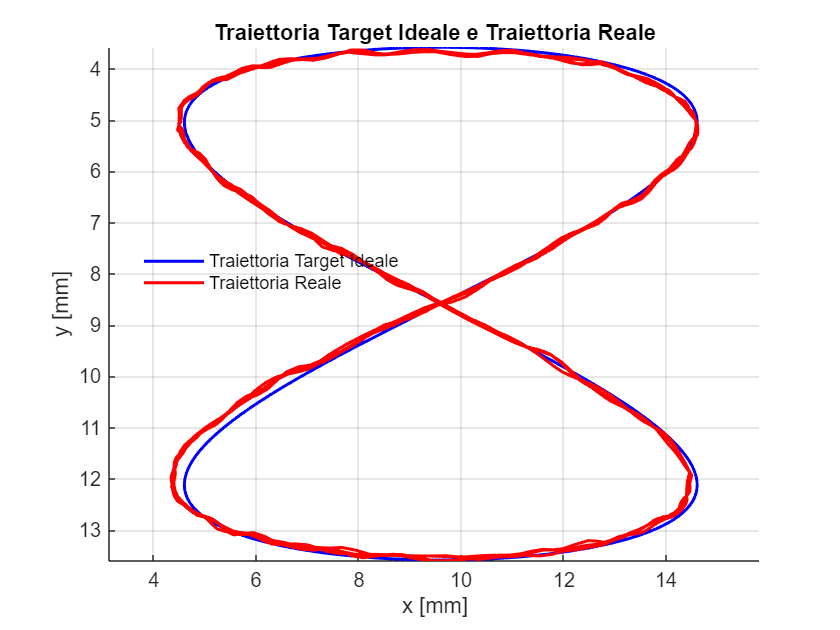

% Plot della figura a 8
figure;
plot(roll_trajectory, pitch_trajectory, 'b-', 'LineWidth', 1.5);
hold on;
plot(laserWorldPoints_filtered(:,1), laserWorldPoints_filtered(:,2), 'r-', 'LineWidth', 1.5);
xlabel('x [mm]');
ylabel('y [mm]');
title('Traiettoria Target Ideale e Traiettoria Reale');
legend('Traiettoria Target Ideale', 'Traiettoria Reale');
legend box off
legend Location best
grid on;
hold off;
grid on;
axis equal;
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
box off

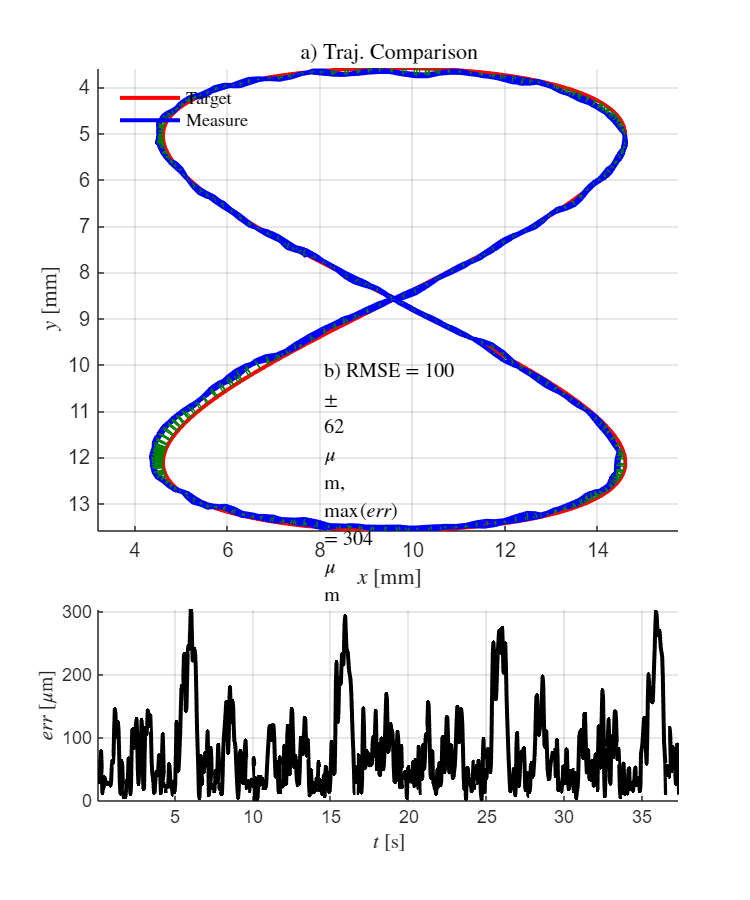

RMSE     = 100 ± 62 µm
max(err) = 304 µm


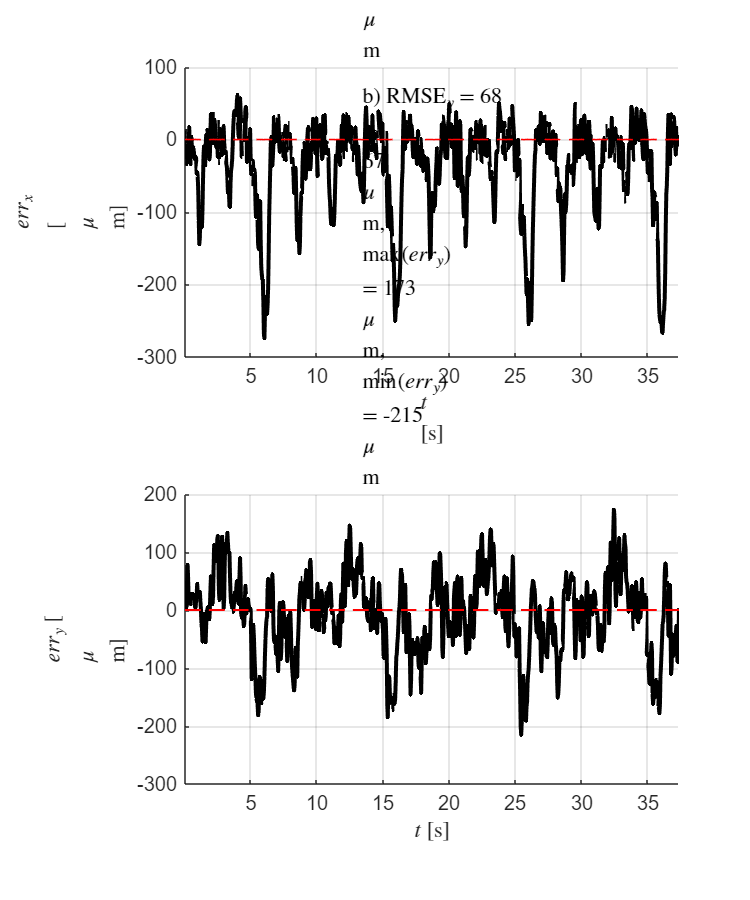

% t is time
t = (1:1:length(coords_matrix(:,2)))'/ video.FrameRate;
[rmse, rmse_x, rmse_y, std_f, std_x ,std_y, figHandles] = circ_rmse(roll_trajectory', pitch_trajectory', laserWorldPoints_filtered(:,1) ,laserWorldPoints_filtered(:,2), t);

rmse_tot = rmse;
std_tot = std_f;
rmse_x = rmse_x;
std_x = std_x;
rmse_y = rmse_y;
std_y = std_y;

data = [rmse_tot, std_tot; rmse_x, std_x; rmse_y, std_y]

data =    99.8390   62.3980
    0.0733    0.0639
    0.0678    0.0674


fileName = fullfile(folder,'data.mat');
save(fileName, 'data');

% Salva solo le figure generate dalla funzione
names = {'Taj_Comparison.fig', 'Axis_Errors.fig'};
for i = 1:numel(figHandles)
    fig = figHandles(i);
    % File name per ciascuna figura
    % figFileName = fullfile(folder, sprintf('CircRMSE_Figure_%d.fig', i));
    figFileName = fullfile(folder, sprintf(names{i}));

    % Salva il file .fig
    savefig(fig, figFileName);
    
end